# **Check how to correct the assumption of AWGN**

## Introduction

Real seismic noise is not AWGN and hence a correction has to be applied to the SNR estimated from the filtered data. This idea is illustrated in the script. 

This script reproduces Figure 4 published in the paper:

Abakumov, I., Roeser, A., and S. A. Shapiro (2020) The arrival time picking uncertainty: theoretical estimationsand their application to microseismic data, Geophysics

**Authors**: I. Abakumov, A. Roeser, S.A. Shapiro

**Publication date**: 20th of February 2020

**E-mail**: abakumov_ivan@mail.ru

## Add MLIB library

In this project we use several functions from MLIB library. 

You can download the whole library at github:

https://github.com/Abakumov/MLIB

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Design low-pass & bandpass filter

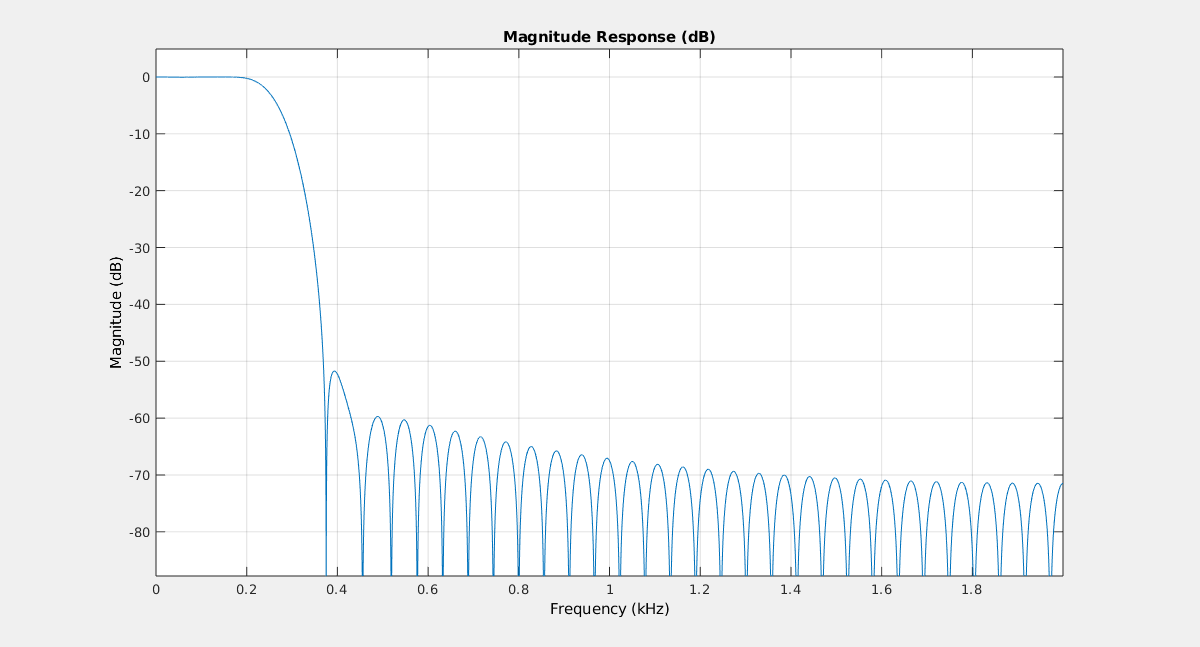

lpFilt = designfilt('lowpassfir','FilterOrder',70, ...
    'CutoffFrequency',275,'SampleRate',4000);
fvtool(lpFilt)

## Definition of basic values

Fs = 4000;              % sampling frequency
dt = 1/Fs;              % time step 
fc = 100;               % dominant frequency of the signal
Td  = 1/fc;             % central period
Ta = 1;                 % length of a priori interval [0 Ta]
damp  = 400;            % attenuation factor (for signal modeling)
sigma = 0.1;            % variance of noise is equal sigma^2
tau = 0.45242;          % arrival time
t = 0:dt:1-dt;

signal = get_ricker(t,tau,fc);
noise  = get_AWG_noise(t,sigma);
noisySignal = signal + noise; 

noiseft = filtfilt(lpFilt,noise);
signalft = filtfilt(lpFilt,signal);
noisySignalft = filtfilt(lpFilt,noisySignal);

## Estimate SNR

W  = sum(signal.^2)*dt;
N0 = var(noise)*dt;
SNR = W/N0;
SNRdb = 10*log10(SNR);

disp(['True value of SNR: ' num2str(SNRdb) 'dB'])

True value of SNR: 30.7649dB


disp(['Important! Signal must be zero mean: mean(signal) = ' num2str(mean(signal)) ])

Important! Signal must be zero mean: mean(signal) = -6e-19


## Estimate SNR: conventional method

noiseWindow = 1300:1700;
signalWindow = 1790:1890;

WN = sum(noisySignal(signalWindow).^2)*dt;
N0 = var(noisySignal(noiseWindow))*dt;

SNR1 = (WN-N0*length(signalWindow))/N0;
SNRdb1 = 10*log10(SNR1);

disp(['Estimated value of SNR (no filtering): ' num2str(SNRdb1) ' dB'])

Estimated value of SNR (no filtering): 30.9941 dB



WN = sum(noisySignalft(signalWindow).^2)*dt;
N0 = var(noisySignalft(noiseWindow))*dt;

SNR1ft = (WN-N0*length(signalWindow))/N0;
SNRdb1ft = 10*log10(SNR1ft);

disp(['Estimated value of SNR (after filtering): ' num2str(SNRdb1ft) ' dB'])

Estimated value of SNR (after filtering): 40.5568 dB


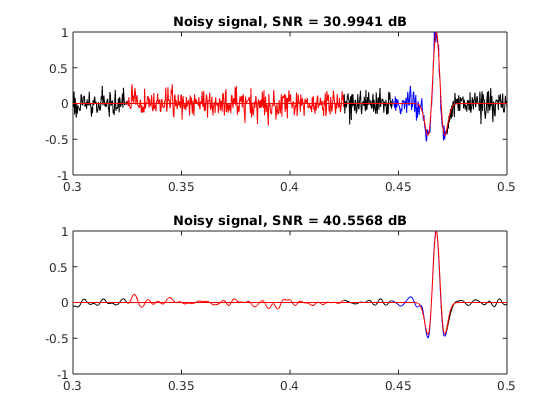



figure(2)
subplot(2,1,1)
plot(t,noisySignal,'black');
hold on
plot(t(noiseWindow),noisySignal(noiseWindow),'red');
plot(t(signalWindow),noisySignal(signalWindow),'blue');
plot(t,signal,'red');
title(['Noisy signal, SNR = ' num2str(SNRdb1) ' dB'])
axis([0.3 0.5 -1 1])

subplot(2,1,2)
plot(t,noisySignalft,'black');
hold on
plot(t(noiseWindow),noisySignalft(noiseWindow),'red');
plot(t(signalWindow),noisySignalft(signalWindow),'blue');
plot(t,signal,'red');
title(['Noisy signal, SNR = ' num2str(SNRdb1ft) ' dB'])
axis([0.3 0.5 -1 1])

## **Numerical estimation of arrival-time uncertainty**

ntest = 10000;
error = zeros(1,ntest);
errorft = zeros(1,ntest);


t0 = 4/fc;

trueSignal = get_ricker(t,t0,fc);
signal = get_ricker(t,tau,fc);
    
for j=1:ntest
    noise  = get_AWG_noise(t,sigma);
    noisySignal = signal + noise;    
    [time,~] = mycorr(trueSignal, noisySignal, dt);
    error(j) = time - tau + t0;
    
    noisySignalft = filtfilt(lpFilt,noisySignal);
    [time,~] = mycorr(trueSignal, noisySignalft, dt);
    errorft(j) = time - tau + t0;
    
end

## Plot results

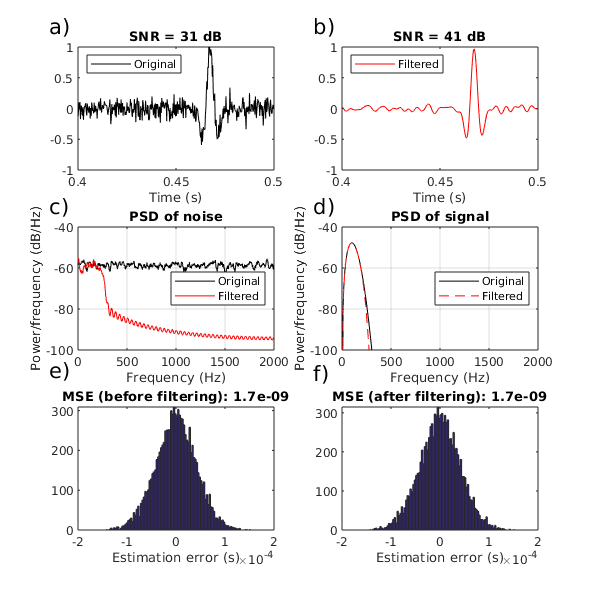

fig = figure(663);
set(fig, 'Position', [100 100 600 600])
subplot(3,2,1)
plot(t,noisySignal,'k')
legend('Original','Location','northwest')
axis([0.4 .5 -1 1])
xlabel('Time (s)')
title(['SNR = ' num2str(SNRdb1,2) ' dB'])
text(0.385, 1.33, 'a)', 'FontSize',16)

subplot(3,2,2)
plot(t,noisySignalft, 'r')
legend('Filtered','Location','northwest')
axis([0.4 .5 -1 1])
xlabel('Time (s)')
title(['SNR = ' num2str(SNRdb1ft,2) ' dB'])
text(0.385, 1.33, 'b)', 'FontSize',16)

subplot(3,2,3)
[f,PSDn] = get_doublesided_PSD(noise,Fs);
plot(f,SME(10*log10(PSDn),10),'k')
hold on
[f,PSDnft] = get_doublesided_PSD(noiseft,Fs);
plot(f,SME(10*log10(PSDnft),10),'-r')
legend('Original','Filtered','Location','east')
title('PSD of noise')
xlabel('Frequency (Hz)')
ylabel('Power/frequency (dB/Hz)')
axis([0 Fs/2 -100 -40])
grid on
text(-300, -30, 'c)', 'FontSize',16)

subplot(3,2,4)
[f,PSDs] = get_doublesided_PSD(signal,Fs);
plot(f,SME(10*log10(PSDs),10),'k')
hold on
[f,PSDsft] = get_doublesided_PSD(signalft,Fs);
plot(f,SME(10*log10(PSDsft),10),'--r')
legend('Original','Filtered','Location','east')
title('PSD of signal')
xlabel('Frequency (Hz)')
ylabel('Power/frequency (dB/Hz)')
axis([0 Fs/2 -100 -40])
grid on
text(-300, -30, 'd)', 'FontSize',16)

subplot(3,2,5)
hist(error,101,'k')
title(['MSE (before filtering): ' num2str(var(error),2)])
xlabel('Estimation error (s)')
text(-2.6e-4, 400, 'e)', 'FontSize',16)

subplot(3,2,6)
hist(errorft,101,'r')
title(['MSE (after filtering): ' num2str(var(errorft),2)])
xlabel('Estimation error (s)')
text(-2.6e-4, 400, 'f)', 'FontSize',16)

get_SB  = @(SNR, Td)(   (Td/(2*pi))^2./SNR   );
disp(['Estimated MSE with SNR= ' num2str(SNRdb1) ' dB: ' num2str(get_SB(10^3.1,Td))])

Estimated MSE with SNR= 30.9941 dB: 2.0121e-09


disp(['Estimated MSE with SNR= ' num2str(SNRdb1ft) ' dB: ' num2str(get_SB(10^4.1,Td))])

Estimated MSE with SNR= 40.5568 dB: 2.0121e-10
